# Analyze chlamy custom multibeta

Live script to visualize plots from evaluate_chlamy_custom_multibeta.m simulation result.

% Setup workspace
clear all;
clc;
close all;
addpath(genpath(".."));

% ASK USER
file_path_usr = "";
lambda_usr = 1;
false;

% Define color scheme
c1 = [206,128,20]./255; %Yellowish
c2 = [0,124,128]./255; % Bluegreensih --> teal
c3 = [123,10,107]./255; %Purpleish
c4 = [40,173,240]./255; % Sky blueish
cg = [213,216,218]./255; %Gray

% Load files
load(file_path_usr);

% Select lambda
lambda_idx = (kernel_result.Lambda == lambda_usr);

% Sort by EMD-values
[~,sorted_idx] = sort(arrayfun(@(i) sum(kernel_result.GP(lambda_idx,i).Sim.EMD_sample,'all')/numel(kernel_result.GP(lambda_idx,i).Sim.EMD_sample), 1:numel(kernel_result.Beta)));
%[~,sorted_idx] = sort(arrayfun(@(i) mean(kernel_result.GP(lambda_idx,i).Sim.EMD_mean), 1:numel(kernel_result.Beta)));
GP = kernel_result.GP(lambda_idx,sorted_idx);
GPIndiv = kernel_result.GPIndiv(:,sorted_idx);
beta_cell = kernel_result.Beta(sorted_idx);
beta_mat = kernel_result.DivBetaMat(sorted_idx);
hyperprior = kernel_result.Hyperprior(sorted_idx);
parameters = kernel_result.Parameters(sorted_idx);

% Calculate average division numbers
x_nu = x_test;
nu = zeros(numel(x_nu),numel(beta_cell));
for beta_idx = 1:size(nu,2)
    beta_fun = beta_cell{beta_idx};
    for x_idx = 1:numel(x_nu)
        nu(x_idx,beta_idx) = integral(@(xi) beta_fun(xi,x_nu(x_idx)),0,x_nu(x_idx));
    end
end

#### Earth Mover's Distance over diameter measure

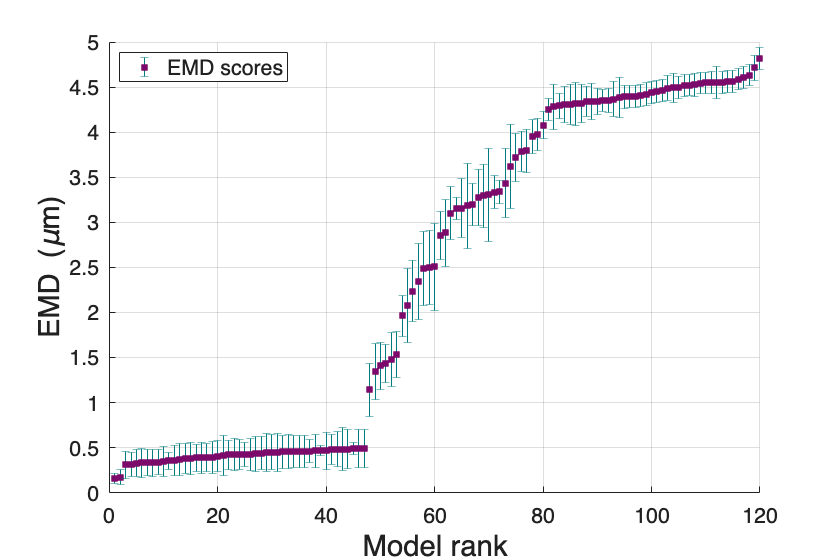

% Plot EMD list
fig_emd = figure();
hold on;
grid on;
set(gca,FontSize=16);
X = 1:numel(beta_cell);
Y_mean = arrayfun(@(i) sum(GP(i).Sim.EMD_sample,'all')/numel(GP(i).Sim.EMD_sample), X);
Y_var = arrayfun(@(i) sum((GP(i).Sim.EMD_sample-Y_mean(i)).^2,'all')/(numel(GP(i).Sim.EMD_sample)-1), X);
errorbar(X,Y_mean,sqrt(Y_var),LineStyle='none',Color=c2,Marker="s",MarkerEdgeColor=c3,MarkerFaceColor=c3);
legend({'EMD scores'},FontSize=16,FontName='Helvetica',Location='NorthWest');
xlabel("Model rank",FontSize=22,FontName='Helvetica');
ylabel("EMD (\mum)",FontSize=22,FontName='Helvetica');
set(gcf,Position=[100,100,560*3/2,560]);

#### NDF, CDF, Division rate, and division number per model index

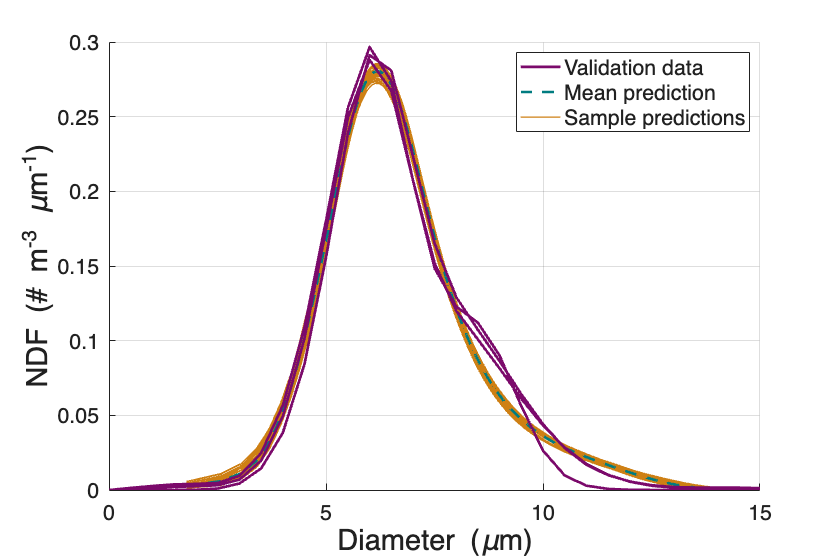

plt_idx = 1;

% Plot NDF and samples
fig_ndf = figure();
hold on;
grid on;
set(gca,FontSize=16);
plot(0,0,Color=c3,LineStyle='-',LineWidth=2);
plot(0,0,Color=c2,LineStyle='--',LineWidth=2);
plot(0,0,Color=c1,LineStyle='-',LineWidth=1);
for i = 1:size(GP(plt_idx).Sim.ndf_sample,2)
    [X, Y] = GP_Gamma.Support.ConvertNDF(GP(plt_idx).Sim.ndf_sample(:,i),GP(plt_idx).Sim.x,D_chlam,dDdx_chlam,Normalize=true);
    plot(X,Y,Color=c1,LineStyle='-',LineWidth=1);
end
[X, Y] = GP_Gamma.Support.ConvertNDF(GP(plt_idx).Sim.ndf_mean,GP(plt_idx).Sim.x,D_chlam,dDdx_chlam,Normalize=true);
plot(X,Y,Color=c2,LineStyle='--',LineWidth=2);
for i = 1:numel(valid_struct.ndf)
    [X, Y] = GP_Gamma.Support.ConvertNDF(valid_struct.ndf{i}.ndf,valid_struct.ndf{i}.x,D_chlam,dDdx_chlam,Normalize=true);
    plot(X,Y,Color=c3,LineStyle='-',LineWidth=2);
end
xlabel("Diameter (\mum)",FontSize=22,FontName='Helvetica');
ylabel("NDF (# m^{-3} \mum^{-1})",FontSize=22,FontName='Helvetica');
legend({'Validation data','Mean prediction','Sample predictions'},FontSize=16,FontName='Helvetica',Location='NorthEast');
set(gcf,Position=[100,100,560*3/2,560]);

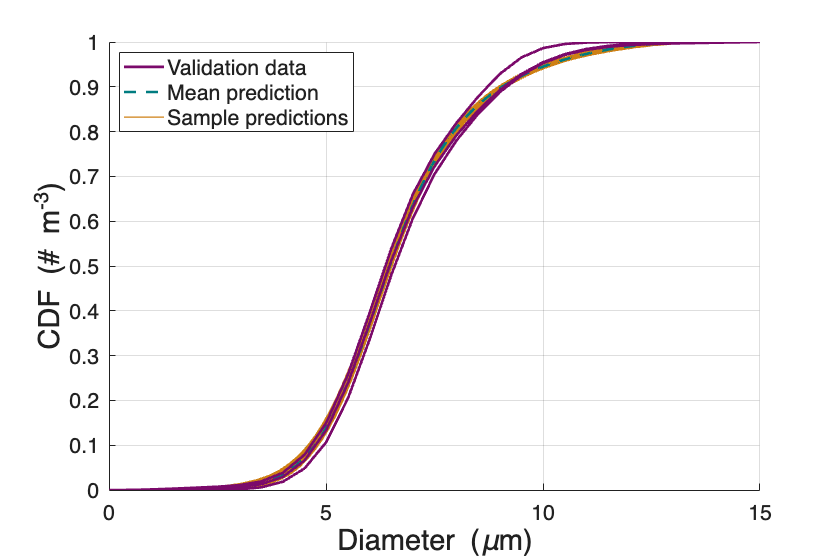


% Plot CDF and samples
fig_cdf = figure();
hold on;
grid on;
set(gca,FontSize=16);
plot(0,0,Color=c3,LineStyle='-',LineWidth=2);
plot(0,0,Color=c2,LineStyle='--',LineWidth=2);
plot(0,0,Color=c1,LineStyle='-',LineWidth=1);
for i = 1:size(GP(plt_idx).Sim.ndf_sample,2)
    X = D_chlam(GP(plt_idx).Sim.x);
    [~, Y] = GP_Gamma.Support.NormalizedProbabilityMetrics(GP(plt_idx).Sim.ndf_sample(:,i),GP(plt_idx).Sim.x);
    plot(X,Y,Color=c1,LineStyle='-',LineWidth=1);
end
X = D_chlam(GP(plt_idx).Sim.x);
[~, Y] = GP_Gamma.Support.NormalizedProbabilityMetrics(GP(plt_idx).Sim.ndf_mean,GP(plt_idx).Sim.x);
plot(X,Y,Color=c2,LineStyle='--',LineWidth=2);
for i = 1:numel(valid_struct.ndf)
    X = D_chlam(valid_struct.ndf{i}.x);
    [~, Y] = GP_Gamma.Support.NormalizedProbabilityMetrics(valid_struct.ndf{i}.ndf,valid_struct.ndf{i}.x);
    plot(X,Y,Color=c3,LineStyle='-',LineWidth=2);
end
xlabel("Diameter (\mum)",FontSize=22,FontName='Helvetica');
ylabel("CDF (# m^{-3})",FontSize=22,FontName='Helvetica');
legend({'Validation data','Mean prediction','Sample predictions'},FontSize=16,FontName='Helvetica',Location='NorthWest');
set(gcf,Position=[100,100,560*3/2,560]);

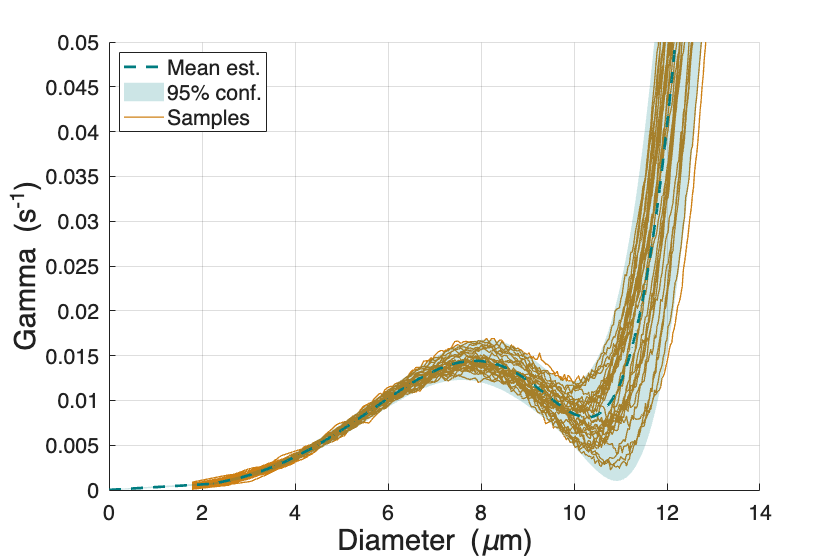


% Plot Gamma and samples
fig_gamma = figure();
hold on;
grid on;
set(gca,FontSize=16);
plot(0,0,LineWidth=2,LineStyle='--',Color=c2);
fill(0,0,c2,FaceAlpha=0.2,EdgeColor='none');
plot(0,0,LineWidth=1,LineStyle='-',Color=c1);
for i = 1:size(GP(plt_idx).Sim.gamma_sample,2)
    X = D_chlam(GP(plt_idx).Sim.x);
    Y = GP(plt_idx).Sim.gamma_sample(:,i);
    plot(X,Y,LineWidth=1,LineStyle='-',Color=c1);
end
alpha = chi2inv(0.95,1);
X = D_chlam(GP(plt_idx).Infer.Posterior.x);
Y_mean = GP(plt_idx).Infer.Posterior.mean;
Y_var = diag(GP(plt_idx).Infer.Posterior.cov);
plot(X,Y_mean,LineWidth=2,LineStyle='--',Color=c2);
fill([X;flip(X)],[Y_mean+sqrt(alpha.*Y_var);flip(Y_mean-sqrt(alpha.*Y_var))],c2,FaceAlpha=0.2,EdgeColor='none');
ylim([0,0.05]);
xlabel("Diameter (\mum)",FontSize=22,FontName='Helvetica');
ylabel("Gamma (s^{-1})",FontSize=22,FontName='Helvetica');
legend({'Mean est.','95% conf.','Samples'},FontSize=16,FontName='Helvetica',Location='NorthWest');
set(gcf,Position=[100,100,560*3/2,560]);

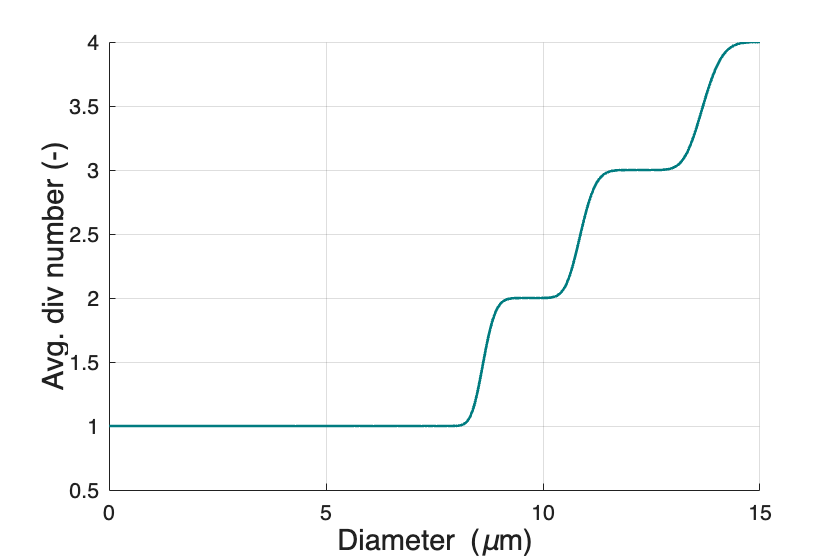


% Plot average division number
fig_nu = figure();
hold on;
grid on;
set(gca,FontSize=16);
X = D_chlam(x_nu);
Y = log2(nu(:,plt_idx));
Y(isinf(Y)) = min(Y(~isinf(Y)));
plot(X, Y, LineWidth=2,Color=c2);
xlabel("Diameter (\mum)",FontSize=22,FontName='Helvetica');
ylabel("Avg. div number (-)",FontSize=22,FontName='Helvetica');
set(gcf,Position=[100,100,560*3/2,560]);

#### Heatmap

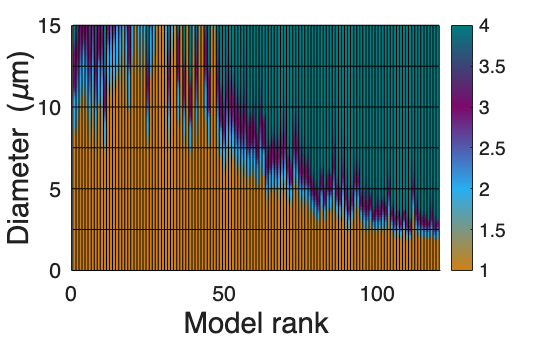

% Xe = 1:numel(beta_cell);
% Ye = D_chlam(x_nu);
% Ze = log2(nu);
% Ze(isinf(Ze)) = min(Ze(~isinf(Ze)));

% Setup colormap
corder = [c1;c4;c2;c3];
corder = [c1;c4;c3;c2];
Nc = 256;
cmap = zeros((size(corder,1)-1)*Nc,3);
for i = 1:(size(corder,1)-1)
    cmap(((i-1)*Nc+1):(i*Nc),:) = corder(i,:) + linspace(0,1,Nc)'.*(corder(i+1,:)-corder(i,:));
end

% Define data
Xe = 1:numel(beta_cell);
Ye = linspace(D_chlam(x_nu(1)),D_chlam(x_nu(end)),100);
Ze = max(log2(interp1(x_nu,nu,x_chlam(Ye)')),1);

%cmap = [linspace(0,1,256)',1-linspace(0,1,256)',zeros(256,1)];

fig_heat = figure();
hold on;
set(gca,FontSize=16);
imagesc([Xe(1),Xe(end)],[Ye(1),Ye(end)],Ze);
colormap(cmap);
colorbar;
axis xy;
xlim([0,1+numel(beta_cell)]);
ylim([min(Ye),max(Ye)]);
xlabel("Model rank",FontSize=22,FontName='Helvetica');
ylabel("Diameter (\mum)",FontSize=22,FontName='Helvetica');

% Vertical help lines
X_help = 0.5+(0:numel(beta_cell));
for xe = X_help
    plot([xe,xe],[Ye(1),Ye(end)],Color='k',LineStyle='-',LineWidth=0.1);
end

% Horizontal help lines
Y_help = 0:2.5:15;
for ye = Y_help
    plot([Xe(1)-0.5,Xe(end)+0.5],[ye,ye],Color='k',LineStyle='-',LineWidth=0.1);
end

#### Plot of model parameters

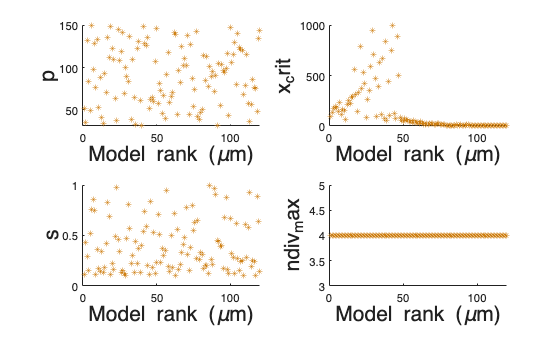

fig_modparams = figure();

X = 1:numel(beta_cell);
Y1 = [parameters.p]';
Y2 = [parameters.x_crit]';
Y3 = [parameters.s]';
Y4 = [parameters.ndiv_max]';


subplot(2,2,1);
scatter(X,Y1,18,MarkerFaceColor=c1,MarkerEdgeColor=c1,Marker='*');
xlabel("Model rank (\mum)",FontSize=16);
ylabel("p",FontSize=16);

subplot(2,2,2);
scatter(X,Y2,18,MarkerFaceColor=c1,MarkerEdgeColor=c1,Marker='*');
xlabel("Model rank (\mum)",FontSize=16);
ylabel("x_crit",FontSize=16);

subplot(2,2,3);
scatter(X,Y3,18,MarkerFaceColor=c1,MarkerEdgeColor=c1,Marker='*');
xlabel("Model rank (\mum)",FontSize=16);
ylabel("s",FontSize=16);

subplot(2,2,4);
scatter(X,Y4,18,MarkerFaceColor=c1,MarkerEdgeColor=c1,Marker='*');
xlabel("Model rank (\mum)",FontSize=16);
ylabel("ndiv_max",FontSize=16);